# Circular Deblurring Experiments using MRI Data

clear;clc;close all;

%import data
load mri;                               %loads mri video as order-4 tensor
X = squeeze(double(D));                 %gets rid of dimension 1 mode
X = mat2gray(X(:,:,1:12));              %takes only first 12 frames   
[m,n,p] = size(X);                    %m1 = 128, n1 = 128, p = 12

%Using Gaussian Filter

h = fspecial('gaussian',[5,5],2);       %builds a Gaussian low-pass filter
[m1,n1] = size(h);   

%Building circularly blurred images

Y = zeros(m,n,p);
for i = 1:p
    Y(:,:,i) = blurryimage(X(:,:,i), h, [m,n]);
end

%% Creating a t-linear system corresponding to the deblurring problem

X_reorder = reorder_tensor(X,[m,n,p]);      %dimension n*p*m
Y_reorder = reorder_tensor(Y,[m,n,p]);

%Defining the t-linear measurement operator

A = circ_blurring_mxop(h, [m,n,p]);

X0 = zeros(n,p,m);
Xblurry = Y_reorder;

Xblurry = Xblurry(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     

%apply tensor regression technique

[Z,its] = tRGS(A,Y_reorder,Y_reorder,1000);
Z_trgs = recover_img(Z,[m,n,p]);
[Z,its] = tRK(A,Y_reorder,Y_reorder,1000);
Z_trk = recover_img(Z,[m,n,p]);

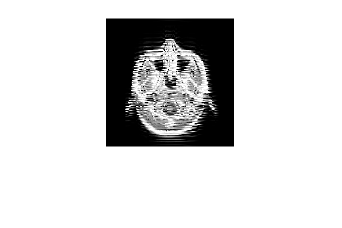

%close all
figure()
imshow(Z_trgs(:,:,1),[0,1])

%imagesc(Y(:,:,1))

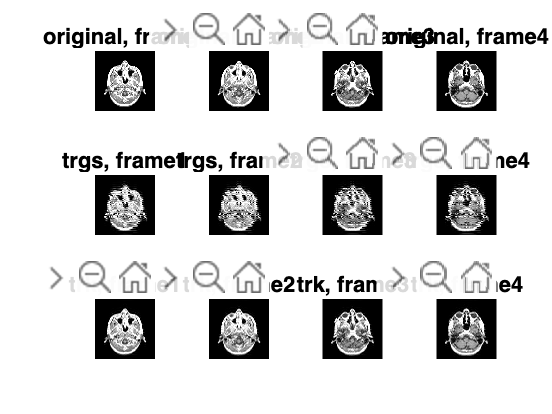

figure
it = 4;
for i = 1:it
    subplot(3,it,i)
    imshow(X(:,:,i),[0,1]);axis image off;
    title(sprintf('original, frame%d',i))

    subplot(3,it,i+it)
    imshow(Z_trgs(:,:,i),[0,1]);axis image off;
    title(sprintf('trgs, frame%d',i))
    
    subplot(3,it,i+2*it)
    imshow(Z_trk(:,:,i));axis image off;
    title(sprintf('trk, frame%d',i))    
end